Primjer 1. 4x4 jednostavna matrica

% matrica povezanosti
G = [0 1 1 0; 0 0 1 0; 1 1 0 0; 1 0 1 0];
disp(G)

     0     1     1     0
     0     0     1     0
     1     1     0     0
     1     0     1     0



n = 4;
tol = 1e-5;
maxit = 1000;
v = ones(n,1) / n;
w = v;
alpha = 0.85;
% prvo koristimo klasicni algoritam
[pr, perm, iter] = PageRank(G,v,w,alpha);
pr

pr =     0.2311    0.3134    0.4180    0.0375


iter

iter = 14

% drugo, implementacija algoritma bez dangling node-ova (sa predavanja)
[pr2, iter2] = PageRankNonDangling(G,v,w,1 - alpha,1e-5,1000)

pr2 =     0.2311
    0.3134
    0.4180
    0.0375


iter2 = 17

## Primjer 2 6x6 Matrica s visecim vrhovima        

% neki kod...



## Primjer 3. Crawler web-matrica

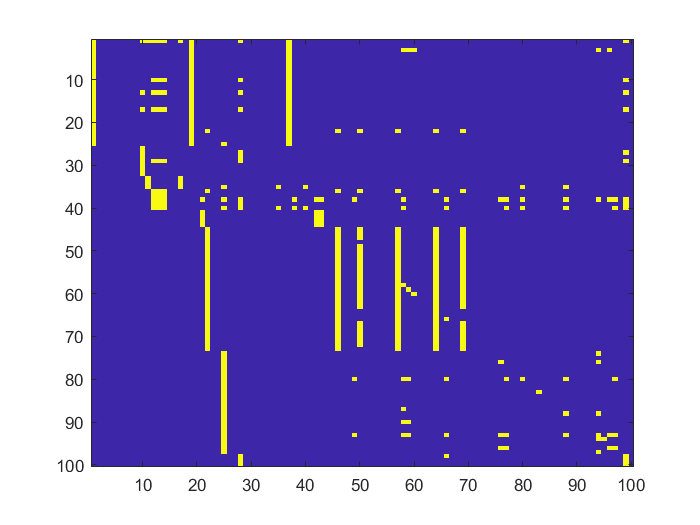

% matrice dobivene pomoću crawler algoritma
load('reddit_domain_G.mat');
load('reddit_domain_U.mat');
n = 100;
v = ones(n,1) / n;
w = v;
alpha = 0.15;
figure(1)
imagesc(G)


% Page Rank
[pr, perm, iter] = PageRank(double(G)', v, w, alpha);
pageRank = pr';
imeStranice = U(perm);
tbl=table(pageRank,imeStranice);
disp(sortrows(tbl,{'pageRank'},{'descend'}))

    pageRank                  imeStranice             
    _________    _____________________________________

      0.16341    'https://www.instagram.com'          
      0.14185    'https://instagram.com'              
      0.04407    'https://www.facebook.com'           
     0.032534    'https://mp.weixin.qq.com'           
     0.016979    'https://twitter.com'                
     0.015304    'https://www.youtube.com'            
     0.014893    'https://schema.org'                 
     0.011616    'https://www.reddit.com'             
     0.010577    'https://wordpress.org'              
     0.010103    'https://creativecommons.org'        
    0.0099234    'https://www.microsoft.com'          
     0.008615    'https://www.redditinc.com'          
     0.008615    'https://www.redditgifts.com'        
    0.0085524    'https://imgur.com'                  
    0.0085524    'https://m.imgur.com'             

## Google webGraph - Primjer sa Kaggle-a

%H = readFromFile();
n = 916428;
edges = 5105039;
%G = makeGoogle(H, edges);
load('VelikiG.mat');

v = ones(n,1) / n;
w = v;
alpha = 0.2;

a = formVector_a(G);
dD = sparseDiagInverse(G * ones(n, 1));
[x, k] = powerMethod(dD', G, ones(1,n) / n, alpha, a, ones(n,1) / n, tol, maxit);

norm(x,1)

ans = 1.0000

k

k = 4

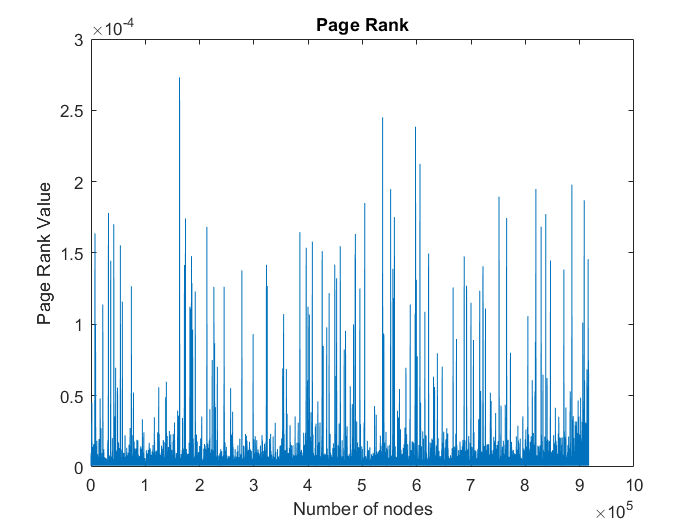


figure(3)
plot(x)
title('Page Rank');
xlabel('Number of nodes')
ylabel('Page Rank Value')